## Parameters


res = 1e3; % Numerical resolution 
l = 1000e-6; % Wavelength
On = 4e-1; % Numerical aperture
Ns = 1.45; % Silica idex
Na = 1; % Air index (for later)
R = 1e-6; % Curvature radius
w0 = 1e-3; % Waist
M = sqrt(pi*w0^2*On/l); % Square root of the beam-quality factor
zr = w0/On; % Rayleigh distance
z0 = 1e2; % Position of the interface
zmax = z0 + R; % Radius of the fiber


## Simulations

% Inline function to compute the Complex beam parameter
q = @(z) z - z0 + 1i*zr;
% Inline function to compute the second-order intensity moment
W = @(z) w0*sqrt(1+(z/z0)^2);

P = [];

% Air/Silica interface ABCD matrix
        A = 1;
        B = 0;
        C = (Na-Ns)/(R*Ns);
        D = Na/Ns;
        Mas = [A,B;
            C,D];
        
x = linspace(-2*w0,2*w0,res); % Transverse coordonates
z = linspace(0,zmax,res); % Propagation coordinates

parfor idx = 1:numel(z)
    zTemp = z(idx); % Retriveing value corresponding to the index (Parellization artefact)
      
    if zTemp == z0
        % Computation of the simulated output complex beam parameter after the interface
        Q2 = Mas*[feval(q,zTemp);1];
        q2 = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing
    else
        % Propagation in the silica ABCD matrix
        B = zTemp; % Position of the considered point (variable)
        C = 0;
        D = 1;
        Mp = [A,B;
            C,D];
        % Computation of the simulated output complex beam parameter
        Q2 = Mp*[feval(q,zTemp);1];
        q2 = Q2(1,1)/Q2(2,1); % Retrieving the first line and normalizing        
    end
    
    % Computation of the real radius
    % R = 1/(1/q2+1i*l*M^2/(pi*Ns*W^2));
    
    % Computation of the intensity on the zTemp-plane
    U = @(x,zTemp) 1/q2^(M^2/2)... <- For readability
        .*(exp(-(1i*pi*x.^2)/(l*q2))...
        .*polyval(hermitePoly(M^2),sqrt(2)*(M.*x)/(feval(W,zTemp))));
    I = abs(feval(U,x,zTemp).^2);
    P = [P;I];
end

## Plotting

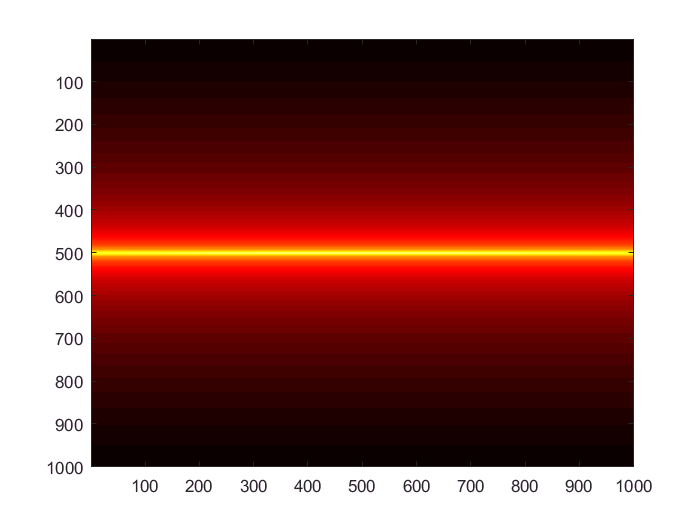

imagesc(P); colormap(hot);